# Problem set # 6

#### **Problem 1: Numerical PDEs:**

clear
s0 = 277.33; % SPY’s closing price on March 6, 2019.
k1 = 285; k2 = 290; 
T = daysact('6-Mar-2019', '30-Sep-2019') / 365;

**1) **

    A call spread is not the same as combination of longing and shorting two calls in the sense that by combination of two call options, we have the right of exercising one without exercising the other, while we can't do that to a single spread. In other words, combination of options gives us more flexibility.

**2)**

r = 2.41 / 100; % 3 Month Treasury Bill Rate from https://ycharts.com/

    Google tells me everything I need. I believe in Google.

**3)**

sigma = (0.1441+0.1344)/2; % 3M calls implied volatility from yahoo finance

    I look up for implied volatility of 3M call option with strike 285 and 290 respectively, and then take the average. I find it reasonable because implied vol derived from BS model is consistent with the geometric brownian motion assumption in this setting.

**4)**

    set smax to be five times deviation away from current price, which is 500, good enough.

smax = 500;

    set M to be 250

M = 250;
hs = smax / M;

    set N to be 20000

N = 20000;
ht = T / N;

    By checking the CFL condition, this setting should be stable. Then set up and explicit Euler discretization of PDE:

si = (hs:hs:(smax-hs))';
tj = (ht:ht:(T-ht))';
ai = (1-sigma^2*si.^2*ht/hs^2-r*ht);
li = (sigma^2*si.^2/2*ht/hs^2-r*si*ht/2/hs);
ui = (sigma^2*si.^2/2*ht/hs^2+r*si*ht/2/hs);
A = zeros(M-1,M-1);
A(1:M:end) = ai;
A(2:M:end) = li(2:end);
A(M:M:end) = ui(1:end-1);

**5)**

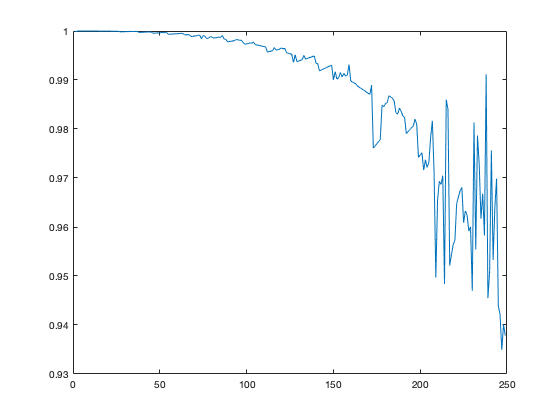

evalue = eig(A);
plot(abs(evalue))

**6）**

cj = NaN(M-1, N-1);
cT = subplus(si - k1) - subplus(si - k2);
bj = zeros(M-1, N-1);
bj(end,:) = ui(end)*(k2-k1)*exp(-r*(T-tj));
bT = ui(end)*(k2-k1);
for j = N-1:-1:1
    if j == N-1
        cj(:,j) = A * cT + bT;
    else 
        cj(:,j) = A * cj(:,j+1) + bj(:,j+1);
    end
end
c1 = cj(floor(s0/hs))

c1 = 1.9566

    today's price is chosen by looking at the location of the vector of prices that equals(closes to) s0.

**7）**

for j = N-1:-1:1
    if j == N-1
        cj(:,j) = A * cT + bT;
        loc = find(cT > cj(:,1));
        cj(loc,j) = cT(loc);
    else 
        cj(:,j) = A * cj(:,j+1) + bj(:,j+1);
        loc = find(cT > cj(:,1));
        cj(loc,j) = cT(loc);
    end
end
c2 = cj(floor(s0/hs))

c2 = 2.1392

    The price is 2.14, higher than the European counterpart.

**7）**

c2 - c1

ans = 0.1826

    The premium is 0.18. It's reasonable.